# CSSC PID Workshop

## Introduction to the Coupled-Tank System

The Coupled Tanks plant is a “Two-Tank” system consisting of a single pump, two cylindrical tanks, and a water basin. For the purposes of this workshop will be only working with the tank-2. The goal of this workshop is to design a controller for the Coupled-Tank System that can track a reference height that we have specified. This is a very common control problem for liquid-level systems present in industrial applications found in the processing systems of petro-chemical, paper making, and water treatment plants. The schematic below shows the system that you will be working with today. The pump takes in a **voltage input (control)** that then pumps water from the water basin below upwards into tank-2. There is a pressure transducer sensor located at the bottom of the tank that is calibrated to measure the level of water present in the tank, giving us a **measurement (feedback)**  that can be used for designing a controller. 

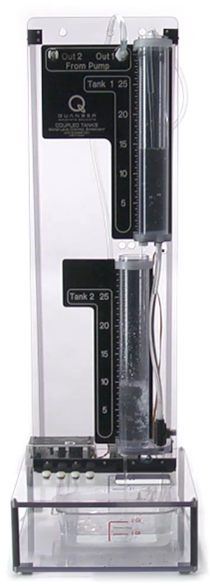       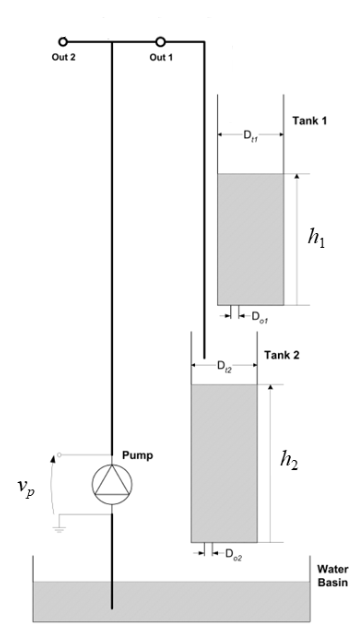

Now let us familiarize ourselves with using the coupled tanks plant experimental system that you will be designing the PID controller for. You will need to follow the following steps to turn on the experimental system and run the PID controller that you have tuned. Make sure that you run the script in MATLAB first before you **Build** and **Start** the system from Simulink.

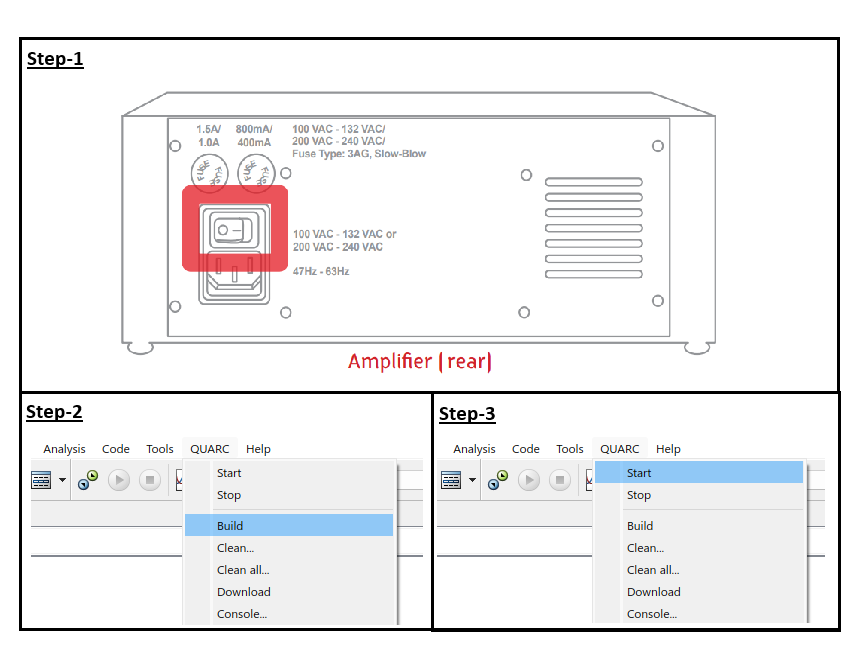

## PID Manual Tuning

 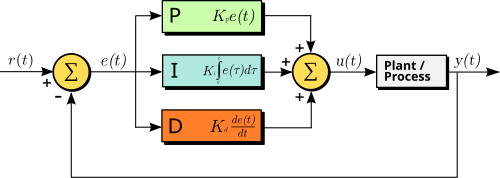

In this section, we will try 


C = 1; % Control Mode


Ref = 0; % Reference Height
V = 0; % Pump Input Voltage


P =0;
I =0;
D =0;


% set_param(gcs, 'SimulationCommand', 'update');

## Ziegler-Nichols PID Tuning

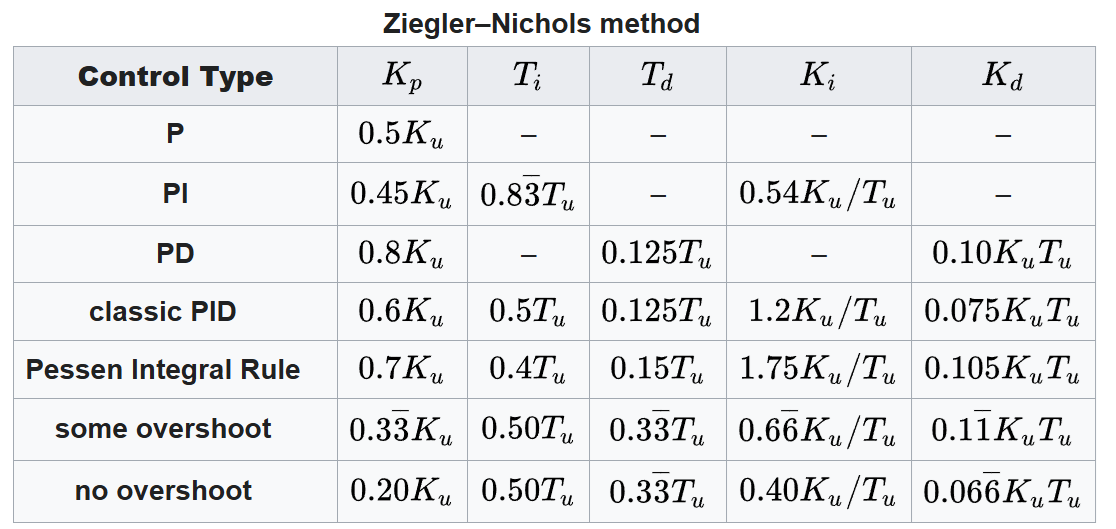


C = 1;  % Control Mode
T = 0;  % Tuning Mode

Ref = 0; % Reference Height
V = 0; % Pump Input Voltage
P =0; % P gain for finding Ku & Tu

controller_type = 'P';

Ku = 15;
Tu = 0.5;

if T == 1
    switch controller_type
        case 'P'
            P = 0.5*Ku;
            I = 0;
            D = 0;
        case 'PI'
            P = 0.45*Ku;
            I = 0.54*Ku/Tu;
            D = 0;
        case 'PID'
            P = 0.2*Ku;
            I = 0.4*Ku/Tu;
            D = 0.066*Ku*Tu;
    end
end

% set_param(gcs, 'SimulationCommand', 'update');

## Integral Anti-Windup

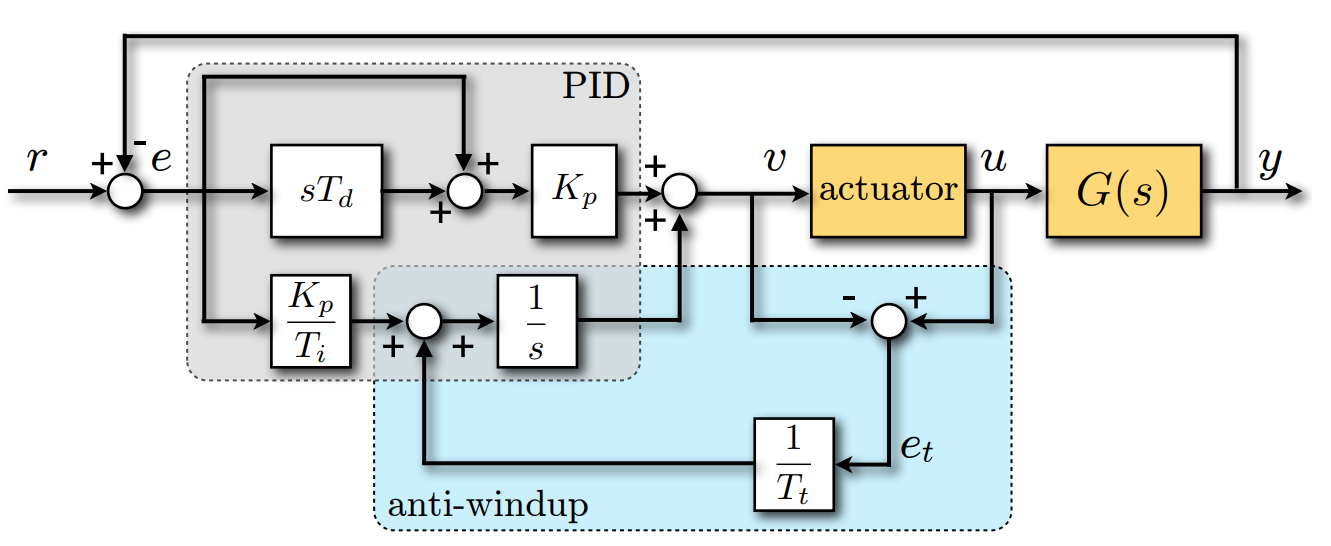

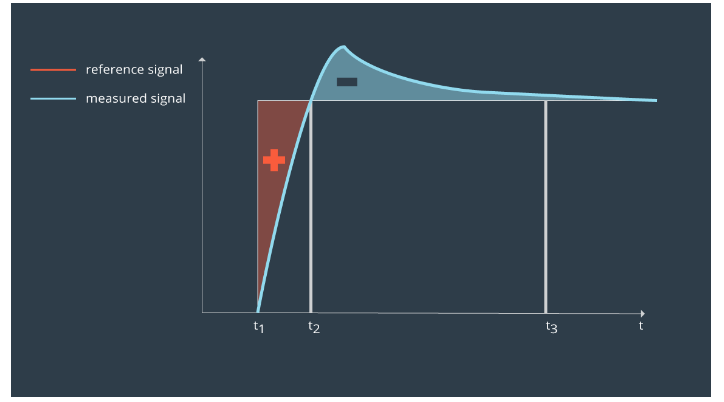


Kb = 500; % Back Calculation Gain

% set_param(gcs, 'SimulationCommand', 'update');

## Gain Scheduling PID